# **Vehicle Performance Analysis (CoDPAD M1-2)**

CoDPAD module 1-2 : Vehicle performance analysis - Basic vehicle characteristics analysis

This part suggests results achieved from fligth test based on refSigTest. Results from raw response data to estimated transfer function will be provided. Please refer to CoDPAD document Ch. 1.1. for further details.

cd(fileparts(matlab.desktop.editor.getActiveFilename))
global calcDensity

## User Input

dataTypeToRefer = 0

dataTypeToRefer = 0

tfFile = load("tfResult.mat")

tfFile = struct with fields:
    tfResult: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}


heaveTfResult = load("heaveTf.mat")

heaveTfResult = struct with fields:
    heaveTfResult: [1×1 struct]


covResult = load("covResult.mat")

covResult = struct with fields:
    covResult: [1×1 struct]


covSampleNum = 10000

covSampleNum = 10000

confidence = 0.9

confidence = 0.9000

calcDensity = 100

calcDensity = 100

covResult = covResult.covResult;
heaveTfResult = heaveTfResult.heaveTfResult;
tfTemp = tfFile.tfResult;

isSweep = dataTypeToRefer;
if isSweep
    if isSweep == 1
        tfTemp(1:9) = [];
    end
end

tfData{1} = tfTemp{1};
tfData{2} = tfTemp{4};
tfData{3} = tfTemp{7};
tfData{4} = tfTemp{2};
tfData{5} = tfTemp{5};
tfData{6} = tfTemp{8};
tfData{7} = tfTemp{3};
tfData{8} = tfTemp{6};
tfData{9} = tfTemp{9};

dataSize = size(tfData,2);


## Basic Dynamic Characteristic Analysis

stepResult = {}; phaseResult = {};
for i = 1:dataSize
    sys = tf(tfData{i}.Num,tfData{i}.Den,'ioDelay',tfData{i}.Delay);
    stepResult{i} = stepinfo(sys);
    [gm,pm,wg,wp] = margin(sys);
    phaseResult{i} = [gm,pm,wg,wp,bandwidth(sys)];
end

#### Step response

stepResultTable = [];
for i = 1:dataSize
    stepResultTable(i,1) = stepResult{i}.RiseTime;
    stepResultTable(i,2) = stepResult{i}.SettlingTime;
    stepResultTable(i,3) = stepResult{i}.Overshoot;
    stepResultTable(i,4) = stepResult{i}.Peak;
    temp = step(tf(tfData{i}.Num,tfData{i}.Den,'ioDelay',tfData{i}.Delay));
    stepResultTable(i,5) = 1 - temp(end);
end

Rise time

Settling time

Overshoot

Peak

SSE

columns = {'Rise time','Settling time','Overshoot','Peak','SSE'};
rows = {'Roll','Pitch','Yaw','u','v','w','X','Y','Z'};
T = table(stepResultTable(:,1),stepResultTable(:,2),stepResultTable(:,3),stepResultTable(:,4),stepResultTable(:,5),'Rownames',rows);
T.Properties.VariableNames = columns

T = 9×5 table
             Rise time    Settling time    Overshoot     Peak          SSE    
             _________    _____________    _________    _______    ___________

    Roll      0.11269        0.43734        9.2489        1.033       0.057749
    Pitch     0.11716        0.83243        18.366       1.0671        0.10045
    Yaw       0.31342        0.98953        4.4529       1.0505       -0.00425
    u         0.41125         3.3962        19.932       1.1991    -0.00094484
    v         0.45583         1.4858        6.2822       1.1276      -0.057896
    w         0.58288          1.619        3.6495       1.0336      0.0025296
    X          8.0355         14.707             0      0.96308 

#### Frequency response

phaseResultTable = [];
for i = 1:dataSize
    phaseResultTable(i,1) = phaseResult{i}(1);
    phaseResultTable(i,2) = phaseResult{i}(2);
    phaseResultTable(i,3) = phaseResult{i}(3);
    phaseResultTable(i,4) = phaseResult{i}(4);
    phaseResultTable(i,5) = phaseResult{i}(5);
end

Bandwidth

GM - PM

columns = {'Gain Margin','Phase Margin','BandWidth'};
rows = {'Roll','Pitch','Yaw','u','v','w','X','Y','Z'};
T = table(phaseResultTable(:,1),phaseResultTable(:,2),phaseResultTable(:,5),'Rownames',rows);
T.Properties.VariableNames = columns

T = 9×3 table
             Gain Margin    Phase Margin    BandWidth
             ___________    ____________    _________

    Roll       1.6113             Inf         18.624 
    Pitch      1.9802           92.91         14.991 
    Yaw        5.0872          140.09         6.6292 
    u          3.4593          109.52         4.2125 
    v          3.4674          101.76         4.6558 
    w          11.575             Inf         3.6542 
    X          15.581             Inf        0.27279 
    Y          33.005             Inf        0.44507 
    Z          56.836          122.75        0.16573 


## Rotating Wing Vehicle flight Performance

#### TRC (Translational Rate Command)

#### Heave response

#### Axis coupling

rows = {'TRC_u';'TRC_v';'Heave Response'};
c1 = [stepResult{4}.RiseTime;stepResult{5}.RiseTime;1/heaveTfResult.Den(2)];
table(c1,'Rownames',rows)

ans = 3×1 table
                        c1   
                      _______

    TRC_u             0.41125
    TRC_v             0.45583
    Heave Response     0.3381


## Disturbance Rejection Performance

#### 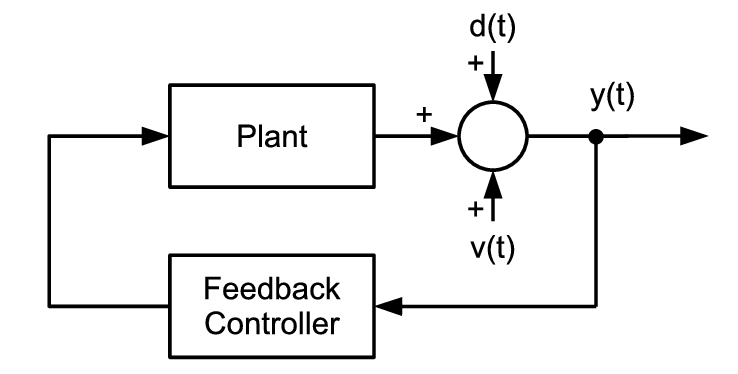

Response of this model can be calculated using,


$$y=\;\frac{\textrm{DG}}{\textrm{DGH}}C+\frac{G}{\textrm{DGH}}W$$


Tranfer function of latter part is called 'sensitivity transfer function' 


$$\frac{G}{\textrm{DGH}}$$


This segment tells us how the system reacts to disturbances. By drawing the Bode plot of this transfer function, DRB and DRP are acquired.

#### DRB

FutureWork

#### DRP

FutureWork

## State Holding Performance

% Generate random variable
stateSize = size(covResult.pos,1);
posHoldSampleData = mvnrnd(zeros(stateSize,1),covResult.pos,covSampleNum);
velHoldSampleData = mvnrnd(zeros(stateSize,1),covResult.vel,covSampleNum);
sampleVariable.pos = posHoldSampleData;
sampleVariable.vel = velHoldSampleData;
save('sampleVariable.mat','sampleVariable');

### Error Analysis

#### Rate error analysis

columns = {'posHold','velHold'};
rows = {'p','q','r'};
T = table(covResult.posHoldStd(1:3)',covResult.velHoldStd(1:3)','Rownames',rows);
T.Properties.VariableNames = columns

T = 3×2 table
         posHold    velHold
         _______    _______

    p    3.5643     10.609 
    q    6.6114     6.2141 
    r    2.0302     2.0371 


#### Attitude error analysis

rows = {'Roll','Pitch','Yaw'};
T = table(covResult.posHoldStd(4:6)',covResult.velHoldStd(4:6)','Rownames',rows);
T.Properties.VariableNames = columns

T = 3×2 table
              posHold      velHold 
             _________    _________

    Roll      0.014904     0.052739
    Pitch       0.0245     0.016493
    Yaw      0.0058168    0.0032981


#### Velocity error analysis

rows = {'u','v','w'};
T = table(covResult.posHoldStd(7:9)',covResult.velHoldStd(7:9)','Rownames',rows);
T.Properties.VariableNames = columns

T = 3×2 table
         posHold     velHold 
         ________    ________

    u    0.066006     0.03409
    v    0.034887     0.90442
    w    0.039506    0.077029


#### Position error analysis

rows = {'X','Y','Z'};
T = table(covResult.posHoldStd(10:12)',covResult.velHoldStd(10:12)','Rownames',rows);
T.Properties.VariableNames = columns

T = 3×2 table
         posHold     velHold
         ________    _______

    X     0.22872    0.21833
    Y    0.070274     6.5406
    Z    0.040005    0.73001


**Ignore Y stdDev for velHold result.*

#### qr error distribution

xIdx = 2;
yIdx = 3;
[pos_confidence_area,pos_out,pos_maxPdf,pos_peripheral,pos_X,pos_Y] = multiVariateAnalysis(xIdx,yIdx,confidence,covResult,sampleVariable,'pos');
[vel_confidence_area,vel_out,vel_maxPdf,vel_peripheral,vel_X,vel_Y] = multiVariateAnalysis(xIdx,yIdx,confidence,covResult,sampleVariable,'vel');
A = [num2str(confidence*100),'% posHold confidence area is ',num2str(pos_confidence_area),' [dps^2]'];
disp(A);

90% posHold confidence area is 193.921 [dps^2]


A = [num2str(confidence*100),'% velHold confidence area is ',num2str(vel_confidence_area),' [dps^2]'];
disp(A);

90% velHold confidence area is 182.8887 [dps^2]


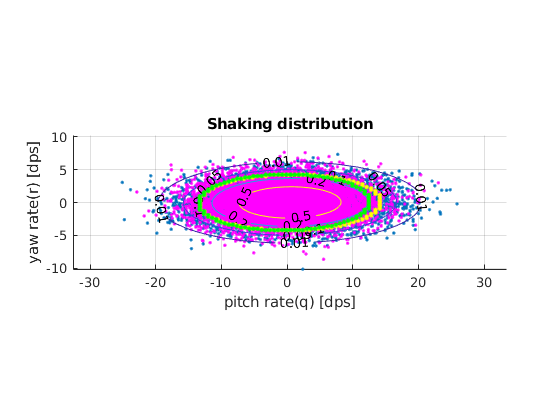


figure(1)
hold on
plot(sampleVariable.pos(:,xIdx)+covResult.posHoldMean(xIdx),sampleVariable.pos(:,yIdx)+covResult.posHoldMean(yIdx),'.')
plot(sampleVariable.vel(:,xIdx)+covResult.velHoldMean(xIdx),sampleVariable.vel(:,yIdx)+covResult.velHoldMean(yIdx),'m.');

contour(pos_X,pos_Y,pos_out/pos_maxPdf,[0.5 0.2 0.1 0.05 0.01],'ShowText','on')
grid on
plot(pos_peripheral(:,1),pos_peripheral(:,2),'.y','MarkerSize',10)
plot(vel_peripheral(:,1),vel_peripheral(:,2),'.g','MarkerSize',10)
axis equal
title('Shaking distribution')
xlabel('pitch rate(q) [dps]')
ylabel('yaw rate(r) [dps]')
hold off

#### PY error distribution 

xIdx = 5;
yIdx = 6;
[pos_confidence_area,pos_out,pos_maxPdf,pos_peripheral,pos_X,pos_Y] = multiVariateAnalysis(xIdx,yIdx,confidence,covResult,sampleVariable,'pos');
[vel_confidence_area,vel_out,vel_maxPdf,vel_peripheral,vel_X,vel_Y] = multiVariateAnalysis(xIdx,yIdx,confidence,covResult,sampleVariable,'vel');
A = [num2str(confidence*100),'% posHold confidence area is ',num2str(pos_confidence_area),' [deg^2]'];
disp(A);

90% posHold confidence area is 0.0020531 [deg^2]


A = [num2str(confidence*100),'% velHold confidence area is ',num2str(vel_confidence_area),' [deg^2]'];
disp(A);

90% velHold confidence area is 0.00072372 [deg^2]


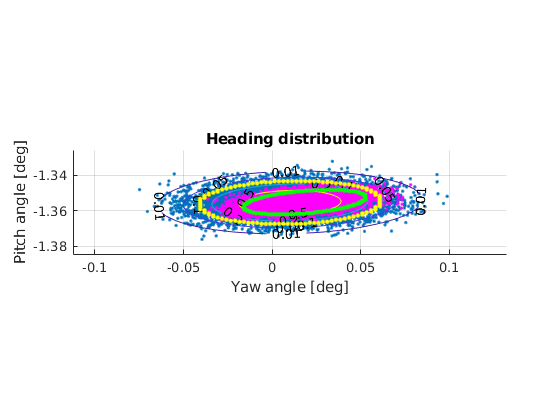


figure(2)
hold on
plot(sampleVariable.pos(:,xIdx)+covResult.posHoldMean(xIdx),sampleVariable.pos(:,yIdx)+covResult.posHoldMean(yIdx),'.')
plot(sampleVariable.vel(:,xIdx)+covResult.velHoldMean(xIdx),sampleVariable.vel(:,yIdx)+covResult.velHoldMean(yIdx),'m.');

contour(pos_X,pos_Y,pos_out/pos_maxPdf,[0.5 0.2 0.1 0.05 0.01],'ShowText','on')
grid on
plot(pos_peripheral(:,1),pos_peripheral(:,2),'.y','MarkerSize',10)
plot(vel_peripheral(:,1),vel_peripheral(:,2),'.g','MarkerSize',10)
axis equal
title('Heading distribution')
xlabel('Yaw angle [deg]')
ylabel('Pitch angle [deg]')

#### RP error distribution 

xIdx = 4;
yIdx = 5;
[pos_confidence_area,pos_out,pos_maxPdf,pos_peripheral,pos_X,pos_Y] = multiVariateAnalysis(xIdx,yIdx,confidence,covResult,sampleVariable,'pos');
[vel_confidence_area,vel_out,vel_maxPdf,vel_peripheral,vel_X,vel_Y] = multiVariateAnalysis(xIdx,yIdx,confidence,covResult,sampleVariable,'vel');
A = [num2str(confidence*100),'% posHold confidence area is ',num2str(pos_confidence_area),' [deg^2]'];
disp(A);

90% posHold confidence area is 0.0051412 [deg^2]


A = [num2str(confidence*100),'% velHold confidence area is ',num2str(vel_confidence_area),' [deg^2]'];
disp(A);

90% velHold confidence area is 0.012531 [deg^2]


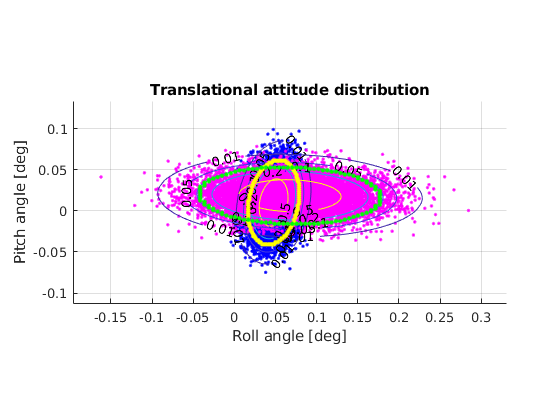


figure(3)
hold on
plot(sampleVariable.pos(:,xIdx)+covResult.posHoldMean(xIdx),sampleVariable.pos(:,yIdx)+covResult.posHoldMean(yIdx),'b.');
plot(sampleVariable.vel(:,xIdx)+covResult.velHoldMean(xIdx),sampleVariable.vel(:,yIdx)+covResult.velHoldMean(yIdx),'m.');

contour(pos_X,pos_Y,pos_out/pos_maxPdf,[0.5 0.2 0.1 0.05 0.01],'ShowText','on')
contour(vel_X,vel_Y,vel_out/vel_maxPdf,[0.5 0.2 0.1 0.05 0.01],'ShowText','on')

grid on
plot(pos_peripheral(:,1),pos_peripheral(:,2),'.y','MarkerSize',10)
plot(vel_peripheral(:,1),vel_peripheral(:,2),'.g','MarkerSize',10)
axis equal
title('Translational attitude distribution')
xlabel('Roll angle [deg]')
ylabel('Pitch angle [deg]')
hold off

#### XY error distribution

xIdx = 10;
yIdx = 11;
[pos_confidence_area,pos_out,pos_maxPdf,pos_peripheral,pos_X,pos_Y] = multiVariateAnalysis(xIdx,yIdx,confidence,covResult,sampleVariable,'pos');
[vel_confidence_area,vel_out,vel_maxPdf,vel_peripheral,vel_X,vel_Y] = multiVariateAnalysis(xIdx,yIdx,confidence,covResult,sampleVariable,'vel');
A = [num2str(confidence*100),'% posHold confidence area is ',num2str(pos_confidence_area),' [m^2]'];
disp(A);

90% posHold confidence area is 0.11283 [m^2]


A = [num2str(confidence*100),'% velHold confidence area is ',num2str(vel_confidence_area),' [m^2]'];
disp(A);

90% velHold confidence area is 17.9214 [m^2]


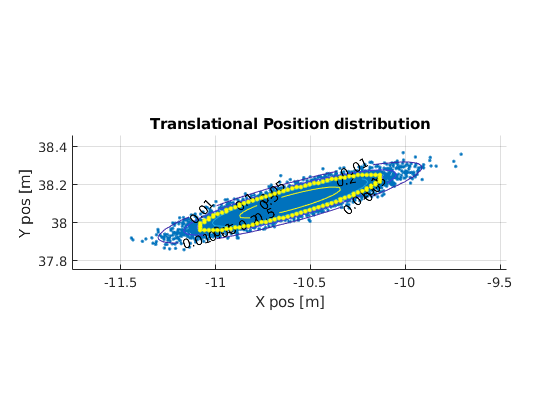


figure(4)
hold on
plot(sampleVariable.pos(:,xIdx)+covResult.posHoldMean(xIdx),sampleVariable.pos(:,yIdx)+covResult.posHoldMean(yIdx),'.')
contour(pos_X,pos_Y,pos_out/pos_maxPdf,[0.5 0.2 0.1 0.05 0.01],'ShowText','on')
grid on
plot(pos_peripheral(:,1),pos_peripheral(:,2),'.y','MarkerSize',10)
% plot(vel_peripheral(:,1),vel_peripheral(:,2),'.g','MarkerSize',5)
axis equal
title('Translational Position distribution')
xlabel('X pos [m]')
ylabel('Y pos [m]')
hold off

## Function definition

function [confidence_area,out,maxPdf,peripheral,X,Y] = multiVariateAnalysis(n,m,confidence,covResult,sampleVariable,mode)
% Internal parameters : DO NOT TOUCH
global calcDensity
level = 1-confidence;
zRange = 5;
cumulated = 0;
index = [];
peripheral = [];
density = calcDensity;

% calculate maxpdf
if(mode == 'pos')
    mu_x = covResult.posHoldMean(n);
    mu_y = covResult.posHoldMean(m);
    std_x = covResult.posHoldStd(n);
    std_y = covResult.posHoldStd(m);
    covar = covResult.pos(n:m,n:m);
elseif(mode == 'vel')
    mu_x = covResult.velHoldMean(n);
    mu_y = covResult.velHoldMean(m);
    std_x = covResult.velHoldStd(n);
    std_y = covResult.velHoldStd(m);
    covar = covResult.vel(n:m,n:m);
end

maxPdf = mvnpdf([mu_x mu_y],[mu_x mu_y],covar);
thres = level * maxPdf;

% distribution data for plotting
[X,Y] = meshgrid(linspace(mu_x-std_x*zRange,mu_x+std_x*zRange,50),linspace(mu_y-std_y*zRange,mu_y+std_y*zRange,50));
out = BiNorm(X,Y,[mu_x;mu_y],covar);

% distribution data for prob. calc.
xGrid = linspace(mu_x-zRange*std_x,mu_x+zRange*std_x,density);
yGrid = linspace(mu_y-zRange*std_y,mu_y+zRange*std_y,density);
xGrid(end) = [];
yGrid(end) = [];
xGridSize = xGrid(2)-xGrid(1);
yGridSize = yGrid(2)-yGrid(1);
gridArea = xGridSize * yGridSize;

for i = xGrid
    for j = yGrid
        if mvnpdf([i j],[mu_x mu_y],covar) >= thres
            cumulated = cumulated + mvncdf([i j],[i+xGridSize j+yGridSize],[mu_x mu_y],covar);
            index = vertcat(index,[i,j]);
        end
    end
end

% cumulated % for verification. This value must be equal to 'confidence' param.

for i = 1:length(index)
    if boxed(i,index,xGridSize,yGridSize)
        peripheral = vertcat(peripheral,index(i,:));
    end
end

confidence_area = length(index) * gridArea;
end

function flag = boxed(n,index,xGridSize,yGridSize)
x = index(n,1); y = index(n,2);
right = 0; left = 0; up = 0; down = 0;
flag = 0;

if isempty(find(abs(index(:,1)-(x+xGridSize)) < xGridSize/2 & abs(index(:,2)-y) < yGridSize/2,1))
    right = 1;
end
if isempty(find(abs(index(:,1)-(x-xGridSize)) < xGridSize/2 & abs(index(:,2)-y) < yGridSize/2,1))
    left = 1;
end
if isempty(find(abs(index(:,1)-x) < xGridSize/2 & abs(index(:,2)-(y+yGridSize)) < yGridSize/2,1))
    up = 1;
end
if isempty(find(abs(index(:,1)-x) < xGridSize/2 & abs(index(:,2)-(y-yGridSize)) < yGridSize/2,1))
    down = 1;
end

if up || down || right || left
    flag = 1;
end

end